## part 1

% doc vision.CascadeObjectDetector
detector = vision.CascadeObjectDetector();
RGB = imread('testowy_0_0000.jpeg');
bboxes = detector(RGB);
liczbaWykrytychTwarzy = size(bboxes,1)

liczbaWykrytychTwarzy = 1

## part 2

% doc detectMinEigenFeatures
GRAY=rgb2gray(RGB);
corners = detectMinEigenFeatures(GRAY);
corners

corners =   2455×1 cornerPoints array with properties:

    Location: [2455×2 single]
      Metric: [2455×1 single]
       Count: 2455


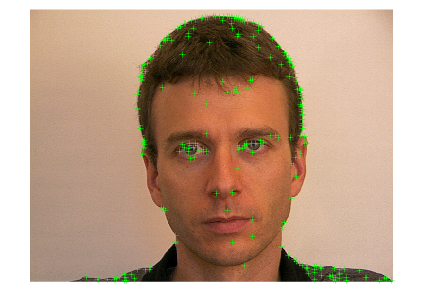

figure; imshow(RGB)
hold on; plot(corners.selectStrongest(250))

## part 3

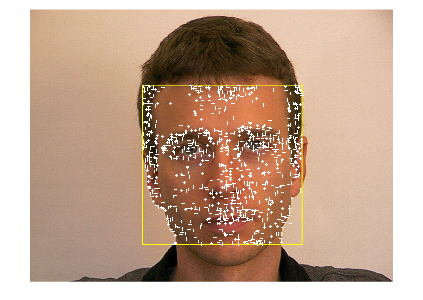

% doc insertShape
% doc insertMarker
% doc bbox2points
corners2 = detectMinEigenFeatures(GRAY, 'ROI', bboxes(1, :));

xyPoints = corners2.Location;
bboxPoints = bbox2points(bboxes(1, :));
bboxPolygon = reshape(bboxPoints', 1, []);
RGB2 = insertShape(RGB, 'Polygon', bboxPolygon, 'LineWidth', 3);
RGB2 = insertMarker(RGB2, xyPoints, '+', 'Color', 'white');
figure; imshow(RGB2)

## part 4

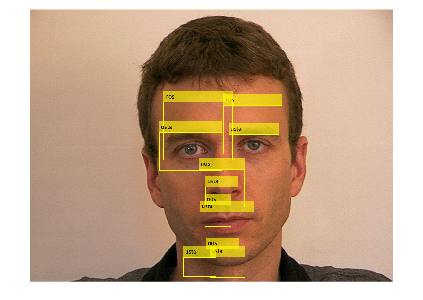

% doc insertObjectAnnotation
noseDetector = vision.CascadeObjectDetector('Nose');
mouthDetector = vision.CascadeObjectDetector('Mouth');

noseBBox1=step(noseDetector, RGB);
mouthBBox1=step(mouthDetector, RGB);

RGB2 = RGB;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox1,'nos');
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',mouthBBox1,'usta');
imshow(RGB2)

## part 5

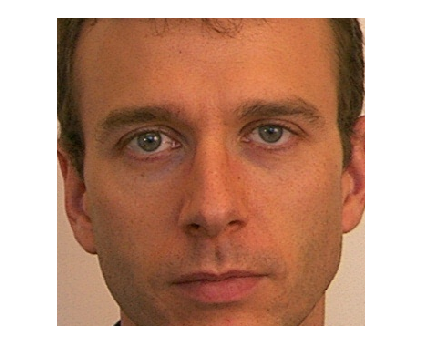

faceIM = imcrop(RGB, bboxes(1, :)); % wycięcie obszaru twarzy 
imshow(faceIM)


% zawężenie detekcji cech tylko do obszaru twarzy
noseBBox2=step(noseDetector, faceIM);
mouthBBox2=step(mouthDetector, faceIM);

% dodatkowe warunki weryfikujące cechy
RGB2 = faceIM;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2,'nos');
figure;subplot(1,2,1);imshow(RGB2)

srodekTwarzy  = [bboxes(1,3)/2 bboxes(1,4)/2]

srodekTwarzy =   168.5000  168.5000


% uwaga bboxes to wspolrzedne przed wycieciem twarzy
srodekNosa = [noseBBox2(:,1)+noseBBox2(:,3)/2 noseBBox2(:,2)+noseBBox2(:,4)/2]

srodekNosa =   162.5000  273.5000
  167.5000  219.0000
  235.5000   95.5000
  122.0000  106.0000


hold on
plot(srodekTwarzy(1),srodekTwarzy(2),'ro')
plot(srodekNosa(:,1),srodekNosa(:,2),'go')

proporcjaObszaruTwarzyiNosa = 0.3;
poleTwarzy    = bboxes(1,3).*bboxes(1,4)

poleTwarzy = 113569

poleNosa      = noseBBox2(:,3).*noseBBox2(:,4)

poleNosa =         2009
        7600
       17017
       20856


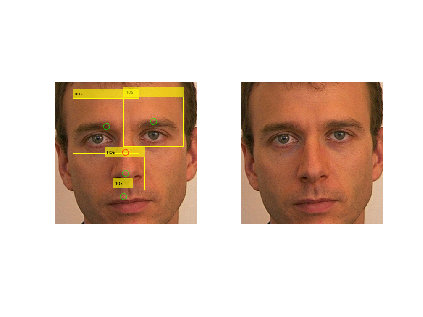

nos_warunek_1 = poleNosa > proporcjaObszaruTwarzyiNosa*poleTwarzy;

noseBBox2A = noseBBox2(nos_warunek_1,:);
RGB2 = faceIM;
RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2A,'nos');
subplot(1,2,2);imshow(RGB2)